close all;
clear all;
clc;


## **Sectiunea 3.1 **

- functia de generare a celor 9 masti:

generate_masks();

- calcularea TX1-TX9 - functia *"calculate_TEM"*

- **normalizare** - functiile *"normalized_TEMs_with_saliency_CT.m"* si *"normalized_TEMs_with_saliency_MRI.m"*

SE = strel('disk', 3); %elementul structural
wv = 'db4'; %tipul de filtrare
N = 10; 

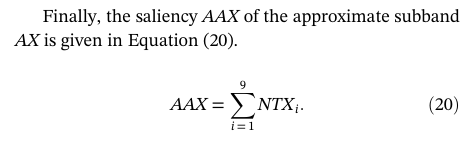

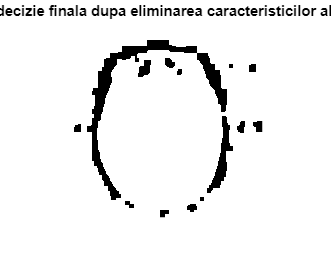

AAX = display_saliency_AAX();

AAY = display_saliency_AAY();

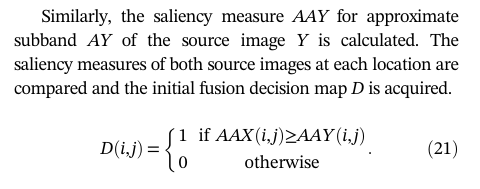

D = display_decision_map_D(AAX, AAY);
CD = close_operation(D, SE);
OD = open_operation(CD, SE);
AD = eliminate_isolated_characteristics(OD, N);
FD = remove_black_spots(AD, N);
%FD = bwareaclose(AD, 3);

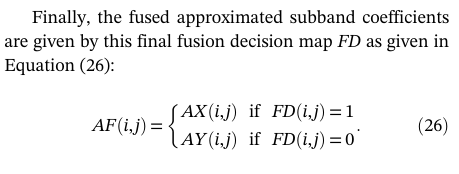

% Inițializare a matricei de coeficienți subbandă fuzionați
AX = swa_CT_image("acute_stroke_CT.jpg");
AY = swa_MRI_image("acute_stroke_MRI.jpg");
AF = zeros(size(AX));

% Selectarea coeficienților din subbanda aproximativă AX sau AY în funcție de valorile din harta de decizie finală FD
AF(FD == 1) = AX(FD == 1);
AF(FD == 0) = AY(FD == 0);

figure,
imshow(uint8(AF)),
title("Subbanda aproximativa - AF");

## Sectiunea 3.2

[swh_CT, swv_CT, swd_CT] = details_CT_image("acute_stroke_CT.jpg");
[swh_MRI, swv_MRI, swd_MRI] = details_MRI_image("acute_stroke_MRI.jpg");

DF1 = sw_details(swh_CT,swh_MRI);
DF2 = sw_details(swv_CT,swv_MRI);
DF3 = sw_details(swd_CT,swd_MRI);

[Lo_R, Hi_R] = wfilters(wv);

## Pasul final - aplicare transformata wavelet inversa


% Transformare inversă a transformării wavelet stationare
fuzionat_final = iswt2(AF, DF1, DF2, DF3, Lo_R, Hi_R);
%%
% Afișarea imaginii fuzionate finale
figure;
imagesc(uint8(fuzionat_final));
colormap(gray);
title('Imaginea fuzionata finala');
%%
figure;
imshow(uint8(fuzionat_final));
title('Imaginea fuzionata finala');


## **Comparatia calitativa**

- **VIFF**

[X, map] = imread("acute_stroke_CT.jpg");
[Y, map] = imread("acute_stroke_MRI.jpg");
imagini_combinate = 0.5 * (double(X) + double(Y)); 
eroare_combinata = abs(imagini_combinate - fuzionat_final);
VIFF = sum(eroare_combinata(:)) / (numel(imagini_combinate) * 255); % normalizarea la intervalul [0, 1]
disp(['Valoarea VIFF pentru comparația combinată cu fuzionat_final este: ', num2str(VIFF)]);

% eroare = abs(double(X) - fuzionat_final);
% VIFF = sum(eroare(:)) / (numel(X) * 255); % normalizarea la intervalul [0, 1]
% disp(['Valoarea VIFF este: ', num2str(VIFF)]);



- **RSF**

% Calculează transformata Fourier a imaginii combinate
ft_combinata = fft2(imagini_combinate);

% Calculează transformata Fourier a imaginii fuzionate
ft_fuzionata = fft2(fuzionat_final);

% Calculează eroarea de frecvență spațială
eroare_RSF = abs(ft_combinata - ft_fuzionata);
% Calculează energia erorii de frecvență spațială
energie_eroare_RSF = sum(abs(eroare_RSF(:)).^2);

% Calculează energia imaginii combinate
energie_combinata = sum(abs(ft_combinata(:)).^2);
% Calculează raportul erorii de frecvență spațială
RSF = energie_eroare_RSF / energie_combinata;
disp(['Valoarea RSF este: ', num2str(RSF)]);


- **QAB/F**

% 1. Calculează imaginea gradient a imaginii originale combinate
gradient_combinat = imgradient(im2gray(imagini_combinate), 'sobel');

% 2. Calculează imaginea gradient a imaginii fuzionate
gradient_fuzionat = imgradient(im2gray(fuzionat_final), 'sobel');

% 3. Calculează metrica QAB/F pe baza gradientului imaginii fuzionate și a gradientului imaginii originale combinate
QABF = sum(sum(abs(gradient_combinat - gradient_fuzionat))) / sum(gradient_combinat(:));

% Afișează valoarea QAB/F
disp(['Valoarea QAB/F este: ', num2str(QABF)]);


- **Q**

Q = ssim(imagini_combinate, fuzionat_final);
disp(['Valoarea SSIM simplu (Q) este: ', num2str(Q)]);

- **QW**

% Calculate the dynamic range of the combined images
dynamic_range = range(imagini_combinate(:));

% Check if the dynamic range is a valid positive number
if ~isnumeric(dynamic_range) || dynamic_range <= 0
    error('The dynamic range of the image must be a positive number.');
end

% Calculate the Gaussian weighting functions
w1 = fspecial('gaussian', 11, 1.5);
w2 = fspecial('gaussian', 11, 1.5);

% Apply the weighting functions to the images
imagini_combinate_weighted = imfilter(imagini_combinate, w1, 'conv', 'replicate');
fuzionat_final_weighted = imfilter(fuzionat_final, w2, 'conv', 'replicate');

% Calculate the SSIM
QW = ssim(imagini_combinate_weighted, fuzionat_final_weighted, 'DynamicRange', dynamic_range);

% Display the value of QW
disp(['Valoarea SSIM ponedarata (QW) este: ', num2str(QW)]);



### ***Functii utilizate***

- generate_masks()

function masks = generate_masks()
    % Definirea măștilor
    masks = zeros(3, 3, 9);
    masks(:,:,1) = [1 2 1; 2 4 2; 1 2 1];
    masks(:,:,2) = [-1 0 1; -2 0 2; -1 0 1];
    masks(:,:,3) = [-1 2 -1; -2 4 -2; -1 2 -1];
    masks(:,:,4) = [1 0 -1; 0 0 0; -1 0 1];
    masks(:,:,5) = [1 -2 1; 0 0 0; -1 2 -1];
    masks(:,:,6) = [-1 -2 -1; 0 0 0; 1 2 1];
    masks(:,:,7) = [1 -2 1; -2 4 -2; 1 -2 1];
    masks(:,:,8) = [-1 -2 -1; 2 4 2; -1 -2 -1];
    masks(:,:,9) = [1 0 -1; -2 0 2; 1 0 -1];
end


- calcuate_TEM()

function TEM = calculate_TEM_CT(AX, mask)
    % Dimensiunea matricei AX
    [rows, cols] = size(AX);
    
    % Initializarea matricei TEM cu zero
    TEM = zeros(rows, cols);
    
    % Calcularea TEM pentru fiecare pixel (i, j)
    for i = 2:rows-1 %pentru a ma asigura ca fiecare pixel are un vecin (se parcurge de la linia 2 si coloana 2)
        for j = 2:cols-1
            % Suma pentru TEM
            temp_sum = 0;
            for p = -1:1
                for q = -1:1
                    % Ridicarea la pătrat și înmulțirea cu masca
                    temp_sum = temp_sum + AX(i+p, j+q)^2 * mask(p+2, q+2);
                end
            end
            % Atribuirea valorii TEM pentru pixelul (i, j)
            TEM(i, j) = temp_sum;
        end
    end
end

function TEM = calculate_TEM_MRI(AY, mask)
    % Dimensiunea matricei AX
    [rows, cols] = size(AY);
    
    % Initializarea matricei TEM cu zero
    TEM = zeros(rows, cols);
    
    % Calcularea TEM pentru fiecare pixel (i, j)
    for i = 2:rows-1 %pentru a ma asigura ca fiecare pixel are un vecin (se parcurge de la linia 2 si coloana 2)
        for j = 2:cols-1
            % Suma pentru TEM
            temp_sum = 0;
            for p = -1:1
                for q = -1:1
                    % Ridicarea la pătrat și înmulțirea cu masca
                    temp_sum = temp_sum + AY(i+p, j+q)^2 * mask(p+2, q+2);
                end
            end
            % Atribuirea valorii TEM pentru pixelul (i, j)
            TEM(i, j) = temp_sum;
        end
    end
end

- normalized_TEMs_with_saliency_CT()

function [NTX, AAX] = normalized_TEMs_with_saliency_CT(swa_img, masks)
    % Crearea unei figuri pentru afișarea matricelor normalizate și a salienței

    % Inițializarea unei variabile pentru stocarea matricelor normalizate
    NTX = cell(1, size(masks, 3));

    % Iterare peste toate mastile
    for i = 1:size(masks, 3)
        % Calcularea TEM folosind funcția calculate_TEM pentru fiecare mască
        TEM = calculate_TEM_CT(swa_img, masks(:,:,i));

        % Calcularea modulului valorilor TEM
        TEM_abs = abs(TEM);

        % Normalizarea matricei TEM la intervalul [0, 1] pe modulul valorilor
        min_val = min(TEM_abs(:));
        max_val = max(TEM_abs(:));
        normalized_TEM = (TEM_abs - min_val) / (max_val - min_val);

        % Calculul salienței AAX pentru subbanda aproximativă AX
        if i == 1
            AAX = normalized_TEM; % Inițializarea salienței AAX cu prima TEM normalizată
        else
            AAX = AAX + normalized_TEM; % Adăugarea valorii normalizate la saliența existentă
        end

        % Stocarea matricei normalizate într-un cell array
        NTX{i} = normalized_TEM;
    end

    % % Afișarea salienței AAX
    % figure;
    % imshow(AAX);
    % title('Saliency AAX pentru subbanda aproximativă AX');
end


- normalized_TEMs_with_saliency_MRI()

function [NTY, AAY] = normalized_TEMs_with_saliency_MRI(swa_img, masks)
    % Crearea unei figuri pentru afișarea matricelor normalizate și a salienței

    % Inițializarea unei variabile pentru stocarea matricilor normalizate
    NTY = cell(1, size(masks, 3));

    % Iterare peste toate mastile
    for i = 1:size(masks, 3)
        % Calcularea TEM folosind funcția calculate_TEM_MRI pentru fiecare mască
        TEM = calculate_TEM_MRI(swa_img, masks(:,:,i));

        % Calcularea modulului valorilor TEM
        TEM_abs = abs(TEM);

        % Normalizarea matricei TEM la intervalul [0, 1] pe modulul valorilor
        min_val = min(TEM_abs(:));
        max_val = max(TEM_abs(:));
        normalized_TEM = (TEM_abs - min_val) / (max_val - min_val);

        % Calculul salienței AAY pentru subbanda aproximativă AY
        if i == 1
            AAY = normalized_TEM; % Inițializarea salienței AAY cu prima TEM normalizată
        else
            AAY = AAY + normalized_TEM; % Adăugarea valorii normalizate la saliența existentă
        end

        % Stocarea matricei normalizate într-un cell array
        NTY{i} = normalized_TEM;
    end

end


- display_saliency_AAX()

function AAX = display_saliency_AAX()
    % Încărcare imagine subbanda aproximativa swa_CT
    swa_CT = imread('acute_stroke_CT.jpg');
    
    % Generare mastile asociate
    masks = generate_masks(); 

    % Apelarea funcției pentru a calcula NTX și AAX
    [NTX, AAX] = normalized_TEMs_with_saliency_CT(swa_CT, masks);

    % Afișarea salienței AAX
    figure;
    imshow(AAX);
    title('Saliency AAX pentru subbanda aproximativă AX');
end

- display_saliency_AAY()

function AAY = display_saliency_AAY()
    % Încărcare imaginea subbandei aproximative swa_MRI
    swa_MRI = imread('acute_stroke_MRI.jpg');
    
    % Generare mastile asociate
    masks = generate_masks(); % Generați mastile folosind funcția generate_masks

    % Apelarea funcției pentru a calcula NTY și AAY
    [NTY, AAY] = normalized_TEMs_with_saliency_MRI(swa_MRI, masks);

    % Afișarea salienței AAY
    figure;
    imshow(AAY);
    title('Saliency AAY pentru subbanda aproximativă AY');
end

- display_decision_map_D()

function D = display_decision_map_D(AAX, AAY)
    % Inițializare matrice D cu valori de zero
    D = zeros(size(AAX));

    % Compar valorile din AAX și AAY și atribui 1 la locațiile unde AAX >= AAY
    D(AAX >= AAY) = 1;

    % Afișare harta deciziilor de fuziune D
    figure;
    imshow(D);
    title('Harta deciziilor de fuziune D');
end

- close_operation()

function CD = close_operation(D, SE)
    % Se creează un element structural de tip disc cu raza specificată
    SE = strel('disk', 3); 

    % Se aplică operația de închidere morfologică pe harta inițială de decizie de fuziune
    CD = imclose(D, SE); 
    
    % Afisare harta de decizie dupa operatia de inchidere morfologica
    figure;
    imshow(CD);
    title('Harta de decizie modificata dupa inchiderea morfologica');
end

- open_operation()

function OD = open_operation(CD, raza_disc)
    % Se creează un element structural de tip disc cu raza specificată
    SE = strel('disk', 3); 
    
    % Aplicarea operației de deschidere pe harta de decizie închisă
    OD = imopen(CD, SE);
    
    % Afișarea hărții de decizie modificată
    figure;
    imshow(OD);
    title('Harta de decizie modificata dupa deschiderea morfologica');
end

- eliminate_isolated_characteristics()

function AD = eliminate_isolated_characteristics(OD, N)
    % Aplicarea operației de deschidere a suprafeței pe harta de decizie modificată
    AD = bwareaopen(OD, N);

    % Afișarea hărții de decizie finală după eliminarea caracteristicilor albe izolate
    figure;
    imshow(AD);
    title('Harta de decizie finala dupa eliminarea caracteristicilor albe izolate');
end

- remove_black_spots()

 function FD = remove_black_spots(AD, N)
    % Negation of the decision map
    neg_AD = ~AD;

    % Applying area opening operation on the negation of the decision map
    neg_FD = bwareaopen(neg_AD, N);

    % Negation of the result
    FD = ~neg_FD;

    % Displaying the final decision map after removing small black spots
    figure;
    imshow(FD);
    title('Final Decision Map after Removing Small Black Spots');
    
 end


- swa_CT_image()

function swa_CT = swa_CT_image(image_path)
    % Citirea imaginii CT
    [X, map] = imread(image_path);
    
    % Executarea transformării wavelet
    [swa_CT, ~, ~, ~] = swt2(X, 1, 'db4');
    
    % Crearea unei noi figuri pentru subploturi
    figure;

    % Afișarea imaginii MRI originală și a subbandei aproximative SWA în același plot
    subplot(1, 2, 1);
    imshow(X, map);
    title('Imagine CT');
    
    subplot(1, 2, 2);
    imshow(uint8(swa_CT));
    title('Aproximare SWA - CT');
end

- swa_MRI_image()

function swa_MRI = swa_MRI_image(image_path)
    % Citirea imaginii MRI
    [Y, map] = imread(image_path);
    
    % Executarea transformării wavelet
    [swa_MRI, ~, ~, ~] = swt2(Y, 1, 'db4');
    
    % Crearea unei noi figuri pentru subploturi
    figure;

    % Afișarea imaginii MRI originală și a subbandei aproximative SWA în același plot
    subplot(1, 2, 1);
    imshow(Y, map);
    title('Imagine MRI');
    
    subplot(1, 2, 2);
    imshow(uint8(swa_MRI));
    title('Aproximare SWA - MRI');
end



- details_CT_image()

function [swh_CT, swv_CT, swd_CT] = details_CT_image(image_path)
    % Citirea imaginii CT
    [X, map] = imread(image_path);
    
    % Executarea transformării wavelet
    [~, swh_CT, swv_CT, swd_CT ] = swt2(X, 1, 'db4');
    
    % Extragerea subbenzilor cu detalii
    % swh = swt_result(:,:,1);
    % swv = swt_result(:,:,2);
    % swd = swt_result(:,:,3);
    
    % Crearea unei noi figuri pentru subploturi
    figure;

    % Afișarea imaginii CT originală și a subbeznilor cu detalii în același plot
    subplot(1, 4, 1);
    imshow(X, map);
    title('Imagine CT');
    
    subplot(1, 4, 2);
    imshow(uint8(swv_CT));
    title('Detalii verticale');
    
    subplot(1, 4, 3);
    imshow(uint8(swh_CT));
    title('Detalii orizontale');
    
    subplot(1, 4, 4);
    imshow(uint8(swd_CT));
    title('Detalii diagonale');
end

- details_MRI_image()

function [swh_MRI, swv_MRI, swd_MRI] = details_MRI_image(image_path)
    % Citirea imaginii MRI
    [X, map] = imread(image_path);
    
    % Executarea transformării wavelet
    [~, swh_MRI, swv_MRI, swd_MRI ] = swt2(X, 1, 'db4');
    
    % Extragerea subbenzilor cu detalii
    % swh = swt_result(:,:,1);
    % swv = swt_result(:,:,2);
    % swd = swt_result(:,:,3);
    
    % Crearea unei noi figuri pentru subploturi
    figure;

    % Afișarea imaginii CT originală și a subbenzilor cu detalii
    subplot(1, 4, 1);
    imshow(X, map);
    title('Imagine MRI');
    
    subplot(1, 4, 2);
    imshow(uint8(swv_MRI));
    title('Detalii verticale');
    
    subplot(1, 4, 3);
    imshow(uint8(swh_MRI));
    title('Detalii orizontale');
    
    subplot(1, 4, 4);
    imshow(uint8(swd_MRI));
    title('Detalii diagonale');
end

- sw_details()

function DF = sw_details(DX,DY)

[m, n] = size(DX);
% Inițializare matrice pentru coeficienții subbenzii cu detalii fuzionați
DF = zeros(m, n);

% Compararea valorilor absolute ale coeficienților și selecția coeficientului fuzionat
for i = 1:m
    for j = 1:n
        if abs(DX(i, j)) >= abs(DY(i, j))
            DF(i, j) = DX(i, j);
        else
            DF(i, j) = DY(i, j);
        end
    end
end
end
